# Clear

clear


## data

load training_data

RGBM = toRGBmatrix([], I1, t1);
RGBM = toRGBmatrix(RGBM, I2, t2);
RGBM = toRGBmatrix(RGBM, I3, t3);
RGBM = toRGBmatrix(RGBM, I4, t4);
RGBM = toRGBmatrix(RGBM, I5, t5);
RGBM = toRGBmatrix(RGBM, I6, t6);
RGBM = toRGBmatrix(RGBM, I7, t7);
RGBM = toRGBmatrix(RGBM, I8, t8);
RGBM = toRGBmatrix(RGBM, I9, t9);
RGBM = toRGBmatrix(RGBM, I10, t10);
RGBM = toRGBmatrix(RGBM, I11, t11);
RGBM = toRGBmatrix(RGBM, I12, t12);
RGBM = toRGBmatrix(RGBM, I13, t13);
RGBM = toRGBmatrix(RGBM, I14, t14);
RGBM = toRGBmatrix(RGBM, I15, t15);
RGBM = toRGBmatrix(RGBM, I16, t16);
RGBM = toRGBmatrix(RGBM, I17, t17);
RGBM = toRGBmatrix(RGBM, I18, t18);
%RGBM = toRGBmatrix(RGBM, I19, t19);
%RGBM = toRGBmatrix(RGBM, I20, t20);
%RGBM = toRGBmatrix(RGBM, I21, t21);
%RGBM = toRGBmatrix(RGBM, I22, t22);
%RGBM = toRGBmatrix(RGBM, I23, t23);


## Train GMM: Find best scaling factor, mean and cov for each K

% expectation
k = 5;


% random for scaling factor, mean and cov
p = 1/k*ones(1,k);
%p = rand(1,k);
meank = rand(3,k)*255;

covk = zeros(3,3,k);
for i = 1:k
    covk(:,:,i) = 0.5*eye(3)*10^4;
end

for j = 1:k
maxi = 30;
i=0;
mean=zeros(3,1);
while i <= maxi && abs(sum(meank(:,j) - mean,'all')) > 1
    
    if i >= 1
        %abs(sum(meank(:,j) - mean,'all'))
        meank(:,j) = mean;
        covk(:,:,j) = cov;
        p(:,j) = p1;
    end

%cluster weight -> we care only one cluster (orange)
cw = clusterweight(RGBM, p, meank, covk, j,k);


%maximization
mean = newmean(RGBM,cw);
cov = newcov(RGBM,cw, mean);
p1 = newp(RGBM,cw);

%check
i=i+1;

end
abs(sum(meank(:,j) - mean,'all'))
meank(:,j) = mean;
covk(:,:,j) = cov;
p(:,j) = p1;
i
j

end

meank
covk
p

%h=error_ellipse(covk(:,:,1))

%test = imread('99.jpg');




## test


test = imread('192.jpg');
sizeM = size(test);
sizeRow = sizeM(1,1);
sizeColumn = sizeM(1,2);
probM = zeros(sizeRow,sizeColumn);
for i = 1:k
    probM = probM + probMatrix(test, covk(:,:,i), meank(:,i), p(:,i));
end


## regionprops

% train

area_1(1) = sum(sum(t1));
area_1(2) = sum(sum(t2));
area_1(3) = sum(sum(t3));
area_1(4) = sum(sum(t4));
area_1(5) = sum(sum(t5));
area_1(6) = sum(sum(t6));
area_1(7) = sum(sum(t7));
area_1(8) = sum(sum(t8));
area_1(9) = sum(sum(t9));
area_1(10) = sum(sum(t10));
area_1(11) = sum(sum(t11));
area_1(12) = sum(sum(t12));
area_1(13) = sum(sum(t13));
area_1(14) = sum(sum(t14));
area_1(15) = sum(sum(t15));
area_1(16) = sum(sum(t16));
area_1(17) = sum(sum(t17));
area_1(18) = sum(sum(t18));
area_1(19) = sum(sum(t19));

dist = [68;76;91;99;106;114;121;137;144;152;160;168;176;192;200;208;216;223;231];
fit_data = fit(area_1',dist,'poly4')

fit_data =      Linear model Poly4:
     fit_data(x) = p1*x^4 + p2*x^3 + p3*x^2 + p4*x + p5
     Coefficients (with 95% confidence bounds):
       p1 =   8.407e-11  (5.206e-11, 1.161e-10)
       p2 =  -4.441e-07  (-5.869e-07, -3.014e-07)
       p3 =   0.0008467  (0.0006351, 0.001058)
       p4 =       -0.73  (-0.8492, -0.6108)
       p5 =       344.2  (323.8, 364.7)

## test



test = imread('106.jpg');
sizeM = size(test);
sizeRow = sizeM(1,1);
sizeColumn = sizeM(1,2);
probM = zeros(sizeRow,sizeColumn);
for i = 1:k
    probM = probM + probMatrix(test, covk(:,:,i), meank(:,i), p(:,i));
end




## w

max1 = max(max(probM))

max1 = 3.4905e-05

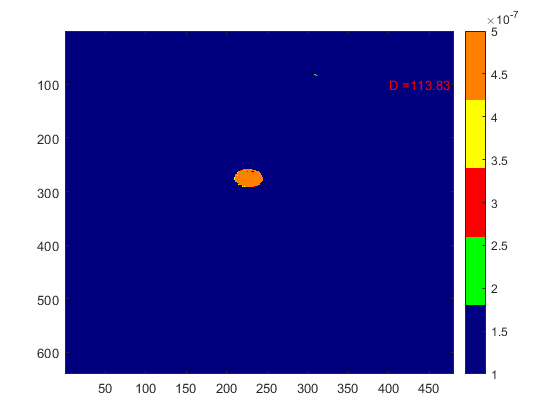


temp = (probM > max1/20);
temp2 = logical(temp);

stats = regionprops(temp2,'Area');
C = cell2mat(struct2cell(stats));
ball_area = C(1,1);
dist = fit_data(ball_area);

runimage(probM,dist)

## run

runimage(probM,0)


## ellipsoid


error_ellipse(covk(:,:,1))

function RGBMatrix = toRGBmatrix(RGBMatrix, Image, Roipoly)
Roipoly = uint8(Roipoly);
R1 = Roipoly.*Image(:,:,1); %Red
G1 = Roipoly.*Image(:,:,2); %Green
B1 = Roipoly.*Image(:,:,3); %Blue

R1 = R1(R1 > 0);
R1 = R1';
G1 = G1(G1 > 0);
G1 = G1';
B1 = B1(B1 > 0);
B1 = B1';

newRGB = [R1; G1; B1];
RGBMatrix = [RGBMatrix newRGB];
end

function cw = clusterweight(data,p,meank,covk,currentk,maxk)
data = double(data);
sizeM = size(data);
sizeColumn = sizeM(1,2);
cw = zeros(1,sizeColumn);

for i = 1:sizeColumn
    sumscale = 0;
    for j = 1:maxk
    scale = scaledg(data,p, meank, covk,i,j);
    sumscale = sumscale + scale;
    end
    cw(1,i) = scaledg(data,p, meank, covk,i,currentk)/sumscale;
end

end

function sg = scaledg(data,p, meank, covk, dataindex,k)
data = double(data);
temp = [data(1,dataindex)-meank(1,k) ; data(2,dataindex)-meank(2,k) ; data(3,dataindex)-meank(3,k)];
sg = p(1,k)*(1/(sqrt((2*pi).^3*det(covk(:,:,k)))))*exp(((-1)/2).*temp'*inv(covk(:,:,k))*temp);
end

function mean = newmean(data, cw)
data = double(data);
dataR = data(1,:);
dataG = data(2,:);
dataB = data(3,:);
meanR = sum(dataR*cw','all')/sum(cw,'all');
meanG = sum(dataG*cw','all')/sum(cw,'all');
meanB = sum(dataB*cw','all')/sum(cw,'all');
%sum(data'.*cw',2)
%meantest = sum(cw'.*data',2)/sum(cw,'all')
mean = [meanR; meanG; meanB];
end

function cov = newcov(data, cw, mean)
data = double(data);
sizeM = size(data);
sizeColumn = sizeM(1,2);
dataR = data(1,:);
dataG = data(2,:);
dataB = data(3,:);
meanR = mean(1,1)*ones(1,sizeColumn);
meanG = mean(2,1)*ones(1,sizeColumn);
meanB = mean(3,1)*ones(1,sizeColumn);
R = dataR - meanR;
G = dataG - meanG;
B = dataB - meanB;

RR=0;
RG=0;
RB=0;
GG=0;
GB=0;
BB=0;

for i= 1:sizeColumn
    RR = RR+cw(1,i)*R(1,i)*R(1,i);
    RG = RG+cw(1,i)*R(1,i)*G(1,i);
    RB = RB+cw(1,i)*R(1,i)*B(1,i);
    GG = GG+cw(1,i)*G(1,i)*G(1,i);
    GB = GB+cw(1,i)*G(1,i)*B(1,i);
    BB = BB+cw(1,i)*B(1,i)*B(1,i);
end

covRR = RR/sum(cw,'all');
covRG = RG/sum(cw,'all');
covRB = RB/sum(cw,'all');
covGG = GG/sum(cw,'all');
covGB = GB/sum(cw,'all');
covBB = BB/sum(cw,'all');

cov = [covRR covRG covRB; covRG covGG covGB; covRB covGB covBB];


end

function p = newp(data,cw)
data = double(data);
sizeM = size(data);
sizeColumn = sizeM(1,2);
p = sum(cw,'all')/sizeColumn;
end

function probM = probMatrix(testImage, covRGB, meanRGB, p1)
sizeM = size(testImage);
sizeRow = sizeM(1,1);
sizeColumn = sizeM(1,2);
probM = zeros(sizeRow,sizeColumn);
testImage = double(testImage);

for i = 1:sizeRow
    for j= 1:sizeColumn
        
    temp = [testImage(i,j,1)-meanRGB(1,1) ; testImage(i,j,2)-meanRGB(2,1) ; testImage(i,j,3)-meanRGB(3,1)];
    probM(i,j) = p1*(1/(sqrt((2*pi).^3*det(covRGB))))*exp(((-1)/2).*temp'*inv(covRGB)*temp);
    
    end
end
end

function runimage(matrix,dist)
figure
mycolors = [0 0 0.5; 0 1 0; 1 0 0; 1 1 0 ; 1 0.5 0];
%mycolors = [0 0 0.5 ; 1 0.5 0];
imagesc(matrix)
colormap(mycolors)
colorbar
caxis([1*10.^(-7) 5*10.^(-7)])
content = "D =" + round(dist,2);
text(400,100,content,'Color','red','FontSize',10);
end

function h=error_ellipse(varargin)
% ERROR_ELLIPSE - plot an error ellipse, or ellipsoid, defining confidence region
%    ERROR_ELLIPSE(C22) - Given a 2x2 covariance matrix, plot the
%    associated error ellipse, at the origin. It returns a graphics handle
%    of the ellipse that was drawn.
%
%    ERROR_ELLIPSE(C33) - Given a 3x3 covariance matrix, plot the
%    associated error ellipsoid, at the origin, as well as its projections
%    onto the three axes. Returns a vector of 4 graphics handles, for the
%    three ellipses (in the X-Y, Y-Z, and Z-X planes, respectively) and for
%    the ellipsoid.
%
%    ERROR_ELLIPSE(C,MU) - Plot the ellipse, or ellipsoid, centered at MU,
%    a vector whose length should match that of C (which is 2x2 or 3x3).
%
%    ERROR_ELLIPSE(...,'Property1',Value1,'Name2',Value2,...) sets the
%    values of specified properties, including:
%      'C' - Alternate method of specifying the covariance matrix
%      'mu' - Alternate method of specifying the ellipse (-oid) center
%      'conf' - A value betwen 0 and 1 specifying the confidence interval.
%        the default is 0.5 which is the 50% error ellipse.
%      'scale' - Allow the plot the be scaled to difference units.
%      'style' - A plotting style used to format ellipses.
%      'clip' - specifies a clipping radius. Portions of the ellipse, -oid,
%        outside the radius will not be shown.
%
%    NOTES: C must be positive definite for this function to work properly.
default_properties = struct(...
  'C', [], ... % The covaraince matrix (required)
  'mu', [], ... % Center of ellipse (optional)
  'conf', 0.5, ... % Percent confidence/100
  'scale', 1, ... % Scale factor, e.g. 1e-3 to plot m as km
  'style', '', ...  % Plot style
  'clip', inf); % Clipping radius
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.C = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.mu = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.conf = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.scale = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & ~ischar(varargin{1})
  error('Invalid parameter/value pair arguments.') 
end
prop = getopt(default_properties, varargin{:});
C = prop.C;
if isempty(prop.mu)
  mu = zeros(length(C),1);
else
  mu = prop.mu;
end
conf = prop.conf;
scale = prop.scale;
style = prop.style;
if conf <= 0 | conf >= 1
  error('conf parameter must be in range 0 to 1, exclusive')
end
[r,c] = size(C);
if r ~= c | (r ~= 2 & r ~= 3)
  error(['Don''t know what to do with ',num2str(r),'x',num2str(c),' matrix'])
end
x0=mu(1);
y0=mu(2);
% Compute quantile for the desired percentile
k = sqrt(qchisq(conf,r)); % r is the number of dimensions (degrees of freedom)
hold_state = get(gca,'nextplot');
if r==3 & c==3
  z0=mu(3);
  
  % Make the matrix has positive eigenvalues - else it's not a valid covariance matrix!
  if any(eig(C) <=0)
    error('The covariance matrix must be positive definite (it has non-positive eigenvalues)')
  end
  % C is 3x3; extract the 2x2 matricies, and plot the associated error
  % ellipses. They are drawn in space, around the ellipsoid; it may be
  % preferable to draw them on the axes.
  Cxy = C(1:2,1:2);
  Cyz = C(2:3,2:3);
  Czx = C([3 1],[3 1]);
  [x,y,z] = getpoints(Cxy,prop.clip);
  h1=plot3(x0+k*x,y0+k*y,z0+k*z,prop.style);hold on
  [y,z,x] = getpoints(Cyz,prop.clip);
  h2=plot3(x0+k*x,y0+k*y,z0+k*z,prop.style);hold on
  [z,x,y] = getpoints(Czx,prop.clip);
  h3=plot3(x0+k*x,y0+k*y,z0+k*z,prop.style);hold on
  
  [eigvec,eigval] = eig(C);
  [X,Y,Z] = ellipsoid(0,0,0,1,1,1);
  XYZ = [X(:),Y(:),Z(:)]*sqrt(eigval)*eigvec';
  
  X(:) = scale*(k*XYZ(:,1)+x0);
  Y(:) = scale*(k*XYZ(:,2)+y0);
  Z(:) = scale*(k*XYZ(:,3)+z0);
  h4=surf(X,Y,Z);
  colormap hsv
  alpha(0.3)
  camlight
  if nargout
    h=[h1 h2 h3 h4];
  end
elseif r==2 & c==2
  % Make the matrix has positive eigenvalues - else it's not a valid covariance matrix!
  if any(eig(C) <=0)
    error('The covariance matrix must be positive definite (it has non-positive eigenvalues)')
  end
  [x,y,z] = getpoints(C,prop.clip);
  h1=plot(scale*(x0+k*x),scale*(y0+k*y),prop.style);
  set(h1,'zdata',z+1)
  if nargout
    h=h1;
  end
else
  error('C (covaraince matrix) must be specified as a 2x2 or 3x3 matrix)')
end
%axis equal
set(gca,'nextplot',hold_state);
end
%---------------------------------------------------------------
% getpoints - Generate x and y points that define an ellipse, given a 2x2
%   covariance matrix, C. z, if requested, is all zeros with same shape as
%   x and y.
function [x,y,z] = getpoints(C,clipping_radius)
n=100; % Number of points around ellipse
p=0:pi/n:2*pi; % angles around a circle
[eigvec,eigval] = eig(C); % Compute eigen-stuff
xy = [cos(p'),sin(p')] * sqrt(eigval) * eigvec'; % Transformation
x = xy(:,1);
y = xy(:,2);
z = zeros(size(x));
% Clip data to a bounding radius
if nargin >= 2
  r = sqrt(sum(xy.^2,2)); % Euclidian distance (distance from center)
  x(r > clipping_radius) = nan;
  y(r > clipping_radius) = nan;
  z(r > clipping_radius) = nan;
end
end
%---------------------------------------------------------------
function x=qchisq(P,n)
% QCHISQ(P,N) - quantile of the chi-square distribution.
if nargin<2
  n=1;
end
s0 = P==0;
s1 = P==1;
s = P>0 & P<1;
x = 0.5*ones(size(P));
x(s0) = -inf;
x(s1) = inf;
x(~(s0|s1|s))=nan;
for ii=1:14
  dx = -(pchisq(x(s),n)-P(s))./dchisq(x(s),n);
  x(s) = x(s)+dx;
  if all(abs(dx) < 1e-6)
    break;
  end
end
end
%---------------------------------------------------------------
function F=pchisq(x,n)
% PCHISQ(X,N) - Probability function of the chi-square distribution.
if nargin<2
  n=1;
end
F=zeros(size(x));
if rem(n,2) == 0
  s = x>0;
  k = 0;
  for jj = 0:n/2-1;
    k = k + (x(s)/2).^jj/factorial(jj);
  end
  F(s) = 1-exp(-x(s)/2).*k;
else
  for ii=1:numel(x)
    if x(ii) > 0
      F(ii) = quadl(@dchisq,0,x(ii),1e-6,0,n);
    else
      F(ii) = 0;
    end
  end
end
end
%---------------------------------------------------------------
function f=dchisq(x,n)
% DCHISQ(X,N) - Density function of the chi-square distribution.
if nargin<2
  n=1;
end
f=zeros(size(x));
s = x>=0;
f(s) = x(s).^(n/2-1).*exp(-x(s)/2)./(2^(n/2)*gamma(n/2));
end
%---------------------------------------------------------------
function properties = getopt(properties,varargin)
%GETOPT - Process paired optional arguments as 'prop1',val1,'prop2',val2,...
%
%   getopt(properties,varargin) returns a modified properties structure,
%   given an initial properties structure, and a list of paired arguments.
%   Each argumnet pair should be of the form property_name,val where
%   property_name is the name of one of the field in properties, and val is
%   the value to be assigned to that structure field.
%
%   No validation of the values is performed.
%
% EXAMPLE:
%   properties = struct('zoom',1.0,'aspect',1.0,'gamma',1.0,'file',[],'bg',[]);
%   properties = getopt(properties,'aspect',0.76,'file','mydata.dat')
% would return:
%   properties = 
%         zoom: 1
%       aspect: 0.7600
%        gamma: 1
%         file: 'mydata.dat'
%           bg: []
%
% Typical usage in a function:
%   properties = getopt(properties,varargin{:})
% Process the properties (optional input arguments)
prop_names = fieldnames(properties);
TargetField = [];
for ii=1:length(varargin)
  arg = varargin{ii};
  if isempty(TargetField)
    if ~ischar(arg)
      error('Propery names must be character strings');
    end
    f = find(strcmp(prop_names, arg));
    if length(f) == 0
      error('%s ',['invalid property ''',arg,'''; must be one of:'],prop_names{:});
    end
    TargetField = arg;
  else
    % properties.(TargetField) = arg; % Ver 6.5 and later only
    properties = setfield(properties, TargetField, arg); % Ver 6.1 friendly
    TargetField = '';
  end
end
if ~isempty(TargetField)
  error('Property names and values must be specified in pairs.');
end
end